## Abdullah Ahmed

aa09303

**Task 1**

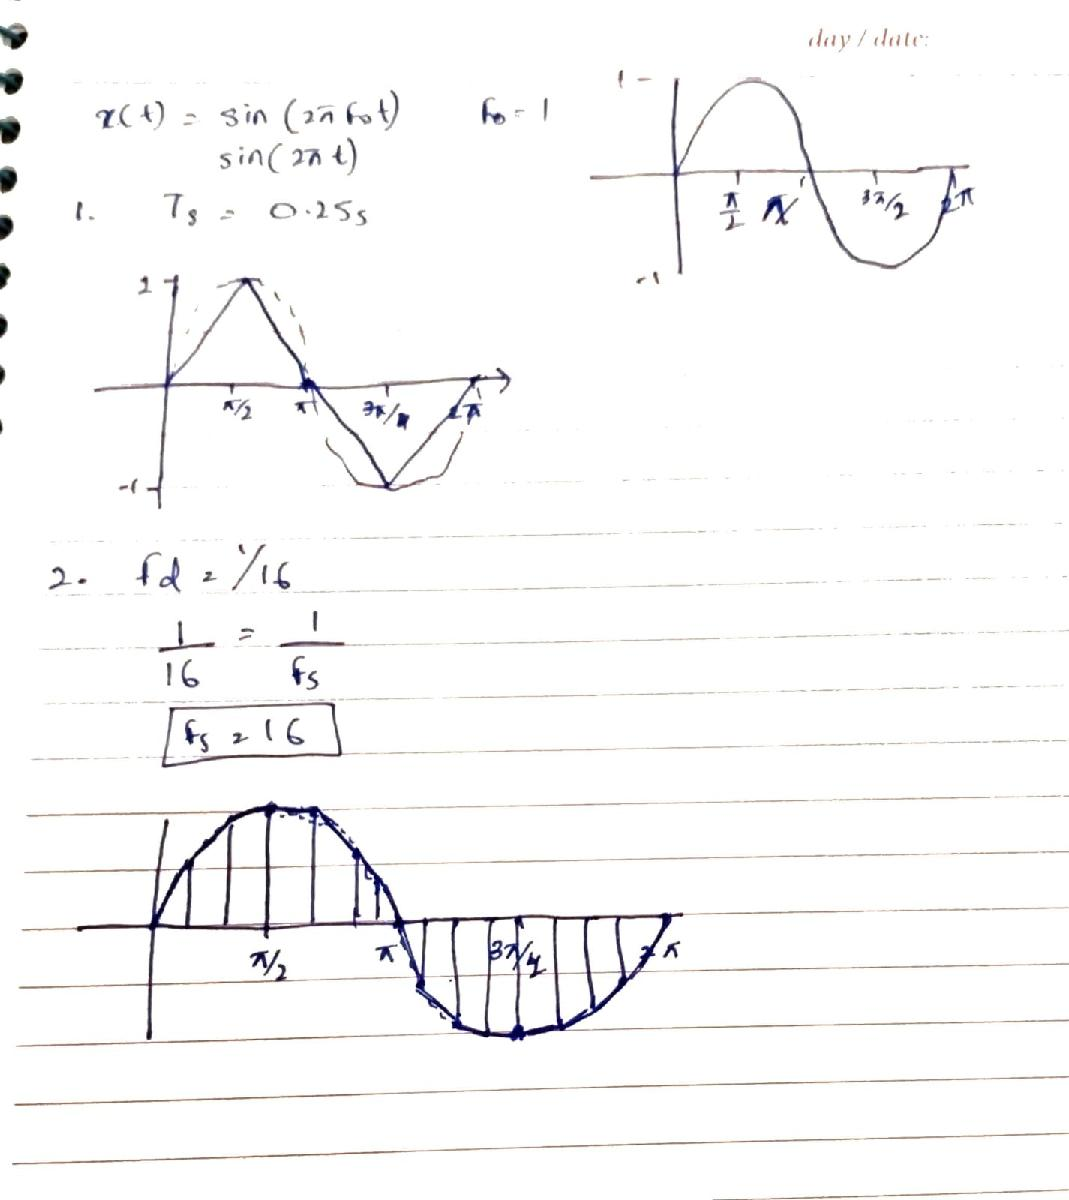

**Task 2**

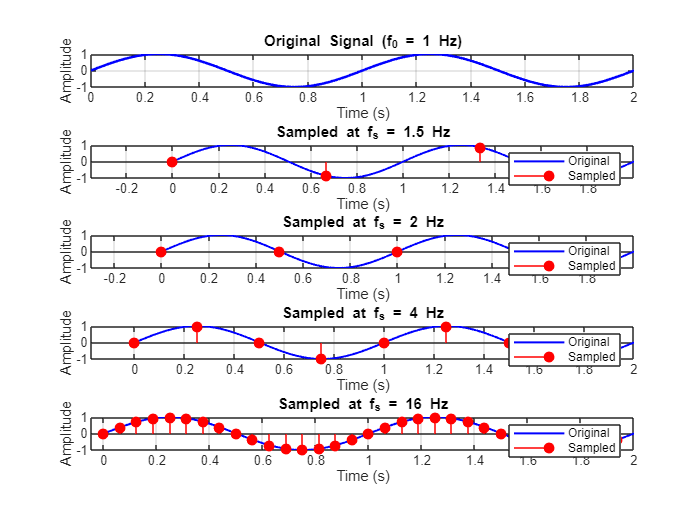

clc;
clear;
close all;

f0 = 1;        % Signal frequency (Hz)
dur = 2;       % Duration (seconds)
T0 = 1/f0;     % Time period of signal
stepsize = 0.01;
tt = 0:stepsize:dur;
xx = sin(2*pi*f0*tt); % Original continuous-time signal

fs_values = [1.5, 2, 4, 16]; % Different sampling frequencies

figure;

% Plot 1: Original signal
subplot(5,1,1);
plot(tt, xx, 'b', 'LineWidth', 1.5);
title('Original Signal (f_0 = 1 Hz)');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

% Plot sampled signals
for i = 1:length(fs_values)
    fs = fs_values(i);
    Ts = 1/fs;
    [x, t] = sampled(f0, fs, dur); % Use blackbox

    subplot(5,1,i+1);
    plot(tt, xx, 'b', 'LineWidth', 1.2); % Original signal
    hold on;
    stem(t, x, 'r', 'filled'); % Sampled signal
    title(['Sampled at f_s = ', num2str(fs), ' Hz']);
    xlabel('Time (s)');
    ylabel('Amplitude');
    legend('Original', 'Sampled');
    grid on;
end

**Observation:**

When the sampling frequency is too low (like 1.5 Hz), the signal looks wrong and doesn’t match the original shape.

At 2 Hz, it matches a bit better but still looks rough.

At 4 Hz and 16 Hz, the samples follow the wave more closely.

So, higher sampling frequencies give a more accurate version of the original signal.

**Task 3**

clc;
clear;
close all;

% Parameters
Fs_list = [1000, 2000, 4000, 16000, 44100]; % Sampling frequencies
ch = 1;              % Mono
nbits = 16;          % Bit depth
Nseconds = 5;        % Duration
datatype = 'int16';  % Data type for getaudiodata

for i = 1:length(Fs_list)
    Fs = Fs_list(i);
    recorder = audiorecorder(Fs, nbits, ch);
    
    fprintf('Recording at %d Hz...\n', Fs);
    disp('Start speaking...');
    recordblocking(recorder, Nseconds);
    disp('End of Recording.');
    
    x = getaudiodata(recorder, datatype);
    
    filename = sprintf('voice_%dHz.wav', Fs);
    audiowrite(filename, x, Fs);
    
    % Get file size
    fileInfo = dir(filename);
    fprintf('Saved: %s (%.2f KB)\n\n', filename, fileInfo.bytes / 1024);
end

Recording at 1000 Hz...


Start speaking...


End of Recording.


Saved: voice_1000Hz.wav (9.81 KB)



Recording at 2000 Hz...


Start speaking...


End of Recording.


Saved: voice_2000Hz.wav (19.57 KB)



Recording at 4000 Hz...


Start speaking...


End of Recording.


Saved: voice_4000Hz.wav (39.11 KB)



Recording at 16000 Hz...


Start speaking...


End of Recording.


Saved: voice_16000Hz.wav (156.29 KB)



Recording at 44100 Hz...


Start speaking...


End of Recording.


Saved: voice_44100Hz.wav (430.71 KB)




disp('All recordings complete.');

All recordings complete.


**Observations:**

As the sampling frequency increases, the recorded audio quality improves significantly.

At **1000 Hz** and **2000 Hz**, the recordings sound very distorted and robotic. Most of the original speech is unintelligible due to under-sampling.

At **4000 Hz**, the clarity improves, but some parts of the speech are still not preserved well.

At **16000 Hz** and especially **44100 Hz**, the recordings sound clear and natural, closely matching the original voice.

Also, the file size increases with sampling rate, since more samples are stored per second. Higher sampling frequencies result in better quality but also larger files.

**Task 4**

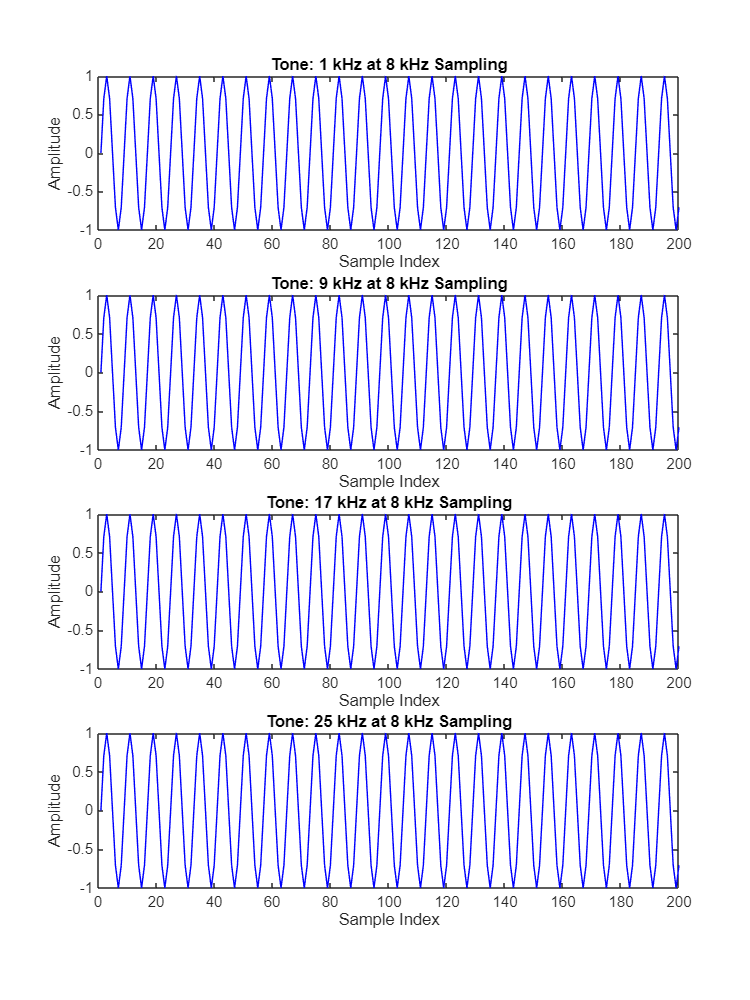

clc;
clear;
close all;

fs = 8000;       % Sampling frequency
dur = 3;         % Duration in seconds
N = fs * dur;    % Total samples
t = 0:1/fs:dur-1/fs;

% Frequencies to test
freqs = [1000, 9000, 17000, 25000];
titles = {'1 kHz', '9 kHz', '17 kHz', '25 kHz'};

figure('Name', 'Sine Waves at Different Frequencies', 'Position', [100 100 600 800]);

for i = 1:4
    f = freqs(i);
    x = sin(2*pi*f*t);
    
    % Play sound
    soundsc(x, fs);
    pause(3.5);
    
    % Plot first 200 samples
    subplot(4,1,i);
    plot(x(1:200), 'b');
    title(['Tone: ' titles{i} ' at 8 kHz Sampling']);
    xlabel('Sample Index');
    ylabel('Amplitude');
end

**Observations:**

**1 kHz tone:** The waveform is smooth and periodic, and the sound is clearly heard. This tone is well within the audible range and accurately represented at 8 kHz sampling frequency (Fs ≥ 2f).

**9 kHz, 17 kHz, and 25 kHz tones:**

Despite being higher than the Nyquist frequency (which is 4 kHz for fs = 8 kHz), sounds are still heard. However, these are not the original tones but their *aliases*.

**why 25kHz can be heard**

Due to **aliasing**. When a signal's frequency is higher than half the sampling rate, it gets **"**folded**"** into a lower frequency component during sampling.

So, a 25 kHz signal sampled at 8 kHz appears as a much lower frequency tone in the audible range, which is what you hear not the original 25 kHz, but its alias.

**Task 5**

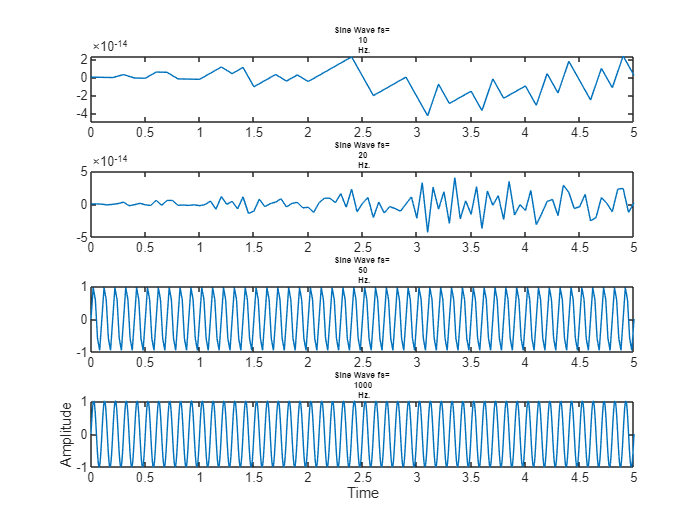

clc;
clear all;
close all;

f0 = 10;
fs = [10 20 50 1000];

for k = 1:length(fs)
    t = 0:1/fs(k):5;
    x = sin(2*pi*f0*t);

    subplot(4,1,k)
    plot(t, x);
    title(["Sine Wave fs= " num2str(fs(k)) " Hz."], 'FontSize', 5);
end

xlabel("Time");
ylabel("Amplitude");

**comments:**

In the first case where fs < 2f0, the sampled signal does not accurately represent the original signal; its period and shape deviate significantly from the original waveform. In the second case where fs = 2f0, the sampled signal starts to align with the period of the original signal resembling more of a triangular pulse. Finally, in the third case where fs > 2f0, the sampled signal closely matches both the period and shape of the original signal. This illustrates the Nyquist Theorem, which asserts that a sampling frequency greater than twice the signal's frequency (2f0) is necessary to accurately reconstruct the analog signal from its discrete samples.